
$$ \frac{\pi^2}{6} = 1 + \frac{1}{2^2} + \frac{1}{3^2} + \cdots.$$


Say $s_k$ is the sum of the first $k$ terms, and $p_k = \sqrt{6s_k}$. 

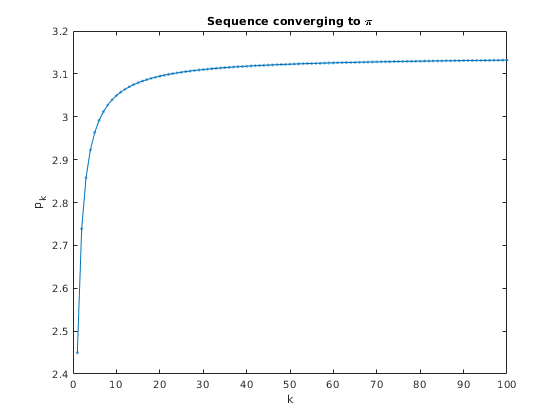

k = (1:100)';
s = cumsum( 1./k.^2 );   % cumulative summation
p = sqrt(6*s);
plot(k,p,'.-')
xlabel('k'), ylabel('p_k')
title('Sequence converging to \pi')

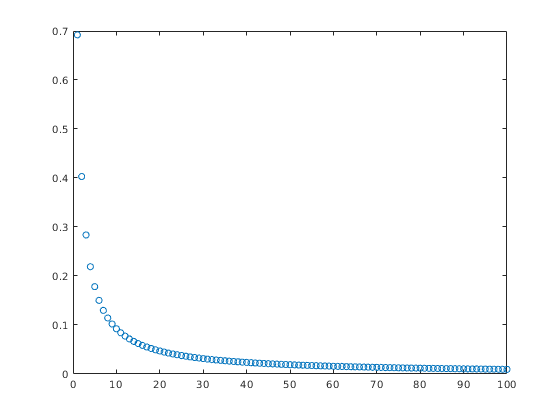

ep = abs(pi-p);    % error sequence
plot(k,ep,'o')

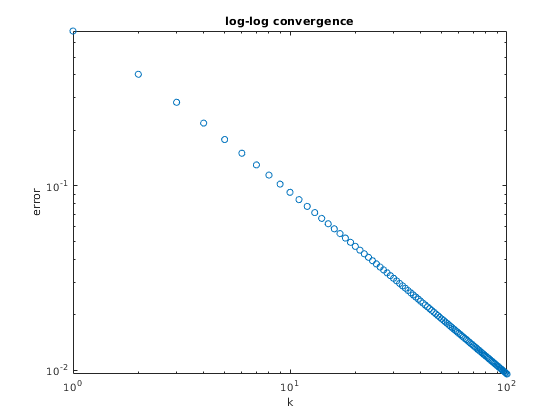

loglog(k,ep,'o'), title('log-log convergence')
xlabel('k'), ylabel('error'),  axis tight

$\epsilon_k\approx a k^b$, or $\log \epsilon_k \approx b (\log k) + \log a$

y = log(ep);
t = log(k);
V = [ t.^0, t ];    
c = V \ y

c =    -0.1824
   -0.9674


In terms of the parameters $a$ and $b$ used above, we have 

a = exp(c(1)),  b = c(2),

a = 0.8333

b = -0.9674

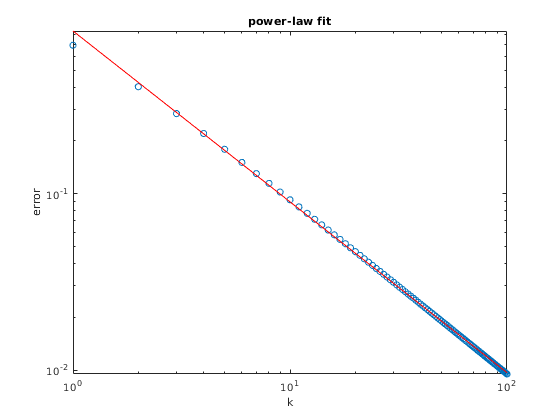

hold on, loglog(k,a*k.^b,'r'), title('power-law fit')